# Matlab第一次大作业

clc,clear;
syms x1 x2 s; %声明符号变量
f1 =2*x1^2+4*x2^2-6*x1-2*x1*x2;%设定目标函数
[k,f1,f2,f3]=grad(f1,x1,x2,s,[5,5],10^(-5));  %设定起始点[x1 x2]=[-2.5,4.25]和精度10^(-2)

k=1, x1=4.459906, x2=0.949292, step=4.086555 f(x1,x2)=8.159198
k=2, x1=2.295935, x2=1.237822, step=2.183122 f(x1,x2)=-2.788080
k=3, x1=2.200325, x2=0.520751, step=0.723417 f(x1,x2)=-4.726006
k=4, x1=1.817251, x2=0.571828, step=0.386464 f(x1,x2)=-5.069065
k=5, x1=1.800326, x2=0.444889, step=0.128062 f(x1,x2)=-5.129794
k=6, x1=1.732513, x2=0.453931, step=0.068413 f(x1,x2)=-5.140545
k=7, x1=1.729517, x2=0.431460, step=0.022670 f(x1,x2)=-5.142448
k=8, x1=1.717512, x2=0.433061, step=0.012111 f(x1,x2)=-5.142785
k=9, x1=1.716982, x2=0.429083, step=0.004013 f(x1,x2)=-5.142844
k=10, x1=1.714857, x2=0.429366, step=0.002144 f(x1,x2)=-5.142855
k=11, x1=1.714763, x2=0.428662, step=0.000710 f(x1,x2)=-5.142857
k=12, x1=1.714387, x2=0.428712, step=0.000380 f(x1,x2)=-5.142857
k=13, x1=1.714370, x2=0.428587, step=0.000126 f(x1,x2)=-5.142857
k=14, x1=1.714304, x2=0.428596, step=0.000067 f(x1,x2)=-5.142857
k=15, x1=1.714301, x2=0.428574, step=0.000022 f(x1,x2)=-5.142857
k=16, x1=1.714289, x2=0.428576, ste

[result]=sprintf('在 %d 次迭代后求出极小值\n',k);%在迭代多少次之后求出极小值
disp(result);

在 17 次迭代后求出极小值



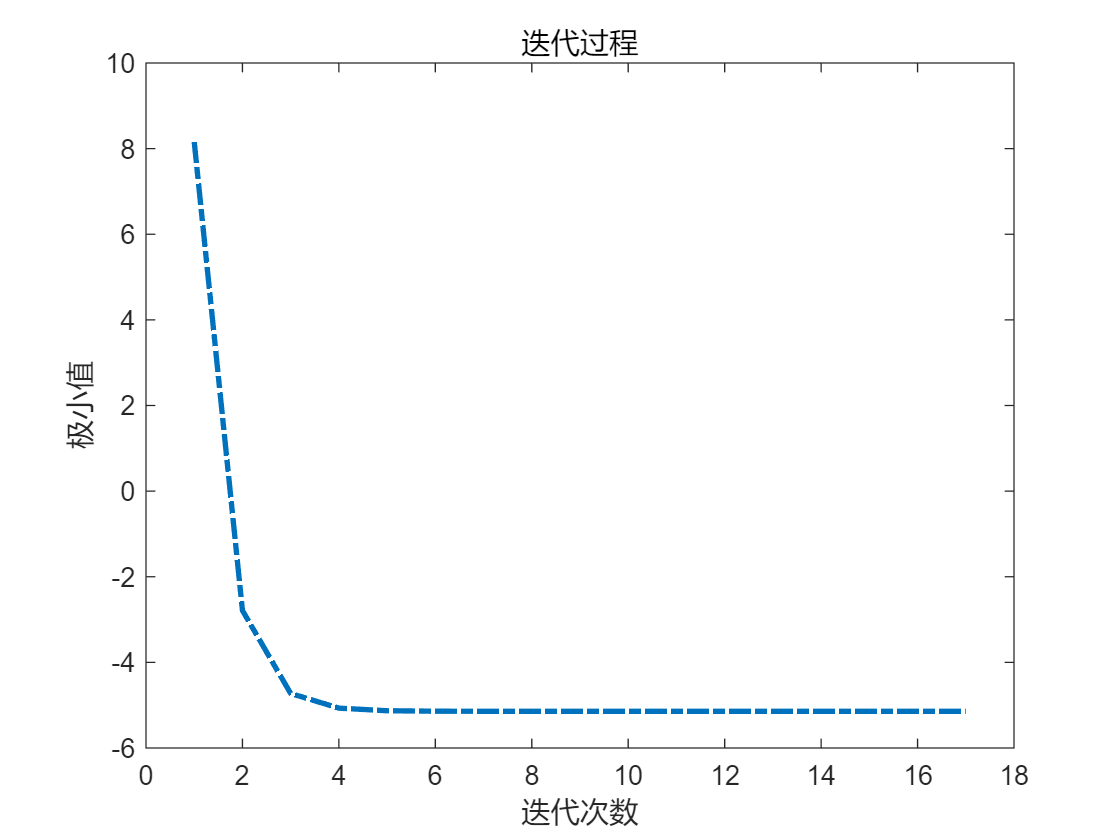

figure(1);
plot(1:k,f3,'MarkerEdgeColor','red','LineStyle','-.','LineWidth',2);
title('迭代过程');
xlabel('迭代次数');
ylabel('极小值');

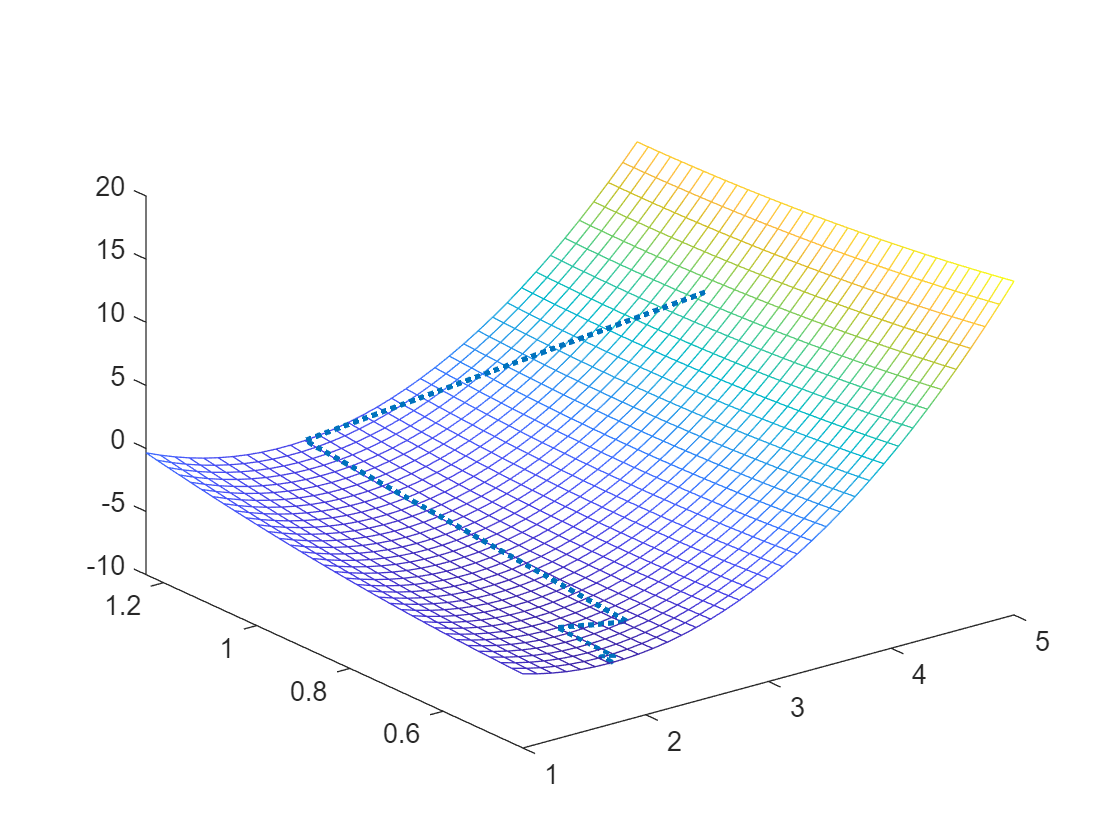

figure(2);
plot3(f1,f2,f3,'LineWidth',2,'LineStyle',':','LineStyleMode','manual','LineJoin','round');
hold on;
syms x1 x2;
f=2*x1^2+4*x2^2-6*x1-2*x1*x2;
fmesh(f);

function   [iterator,f1,f2,f3] = grad(f,x1,x2,s,start_point,thereshold) 
    iterator = 0;%迭代次数赋值初始化
    grad_f = [diff(f,x1) diff(f,x2)]; %计算f的梯度 
    delta = subs(grad_f,[x1,x2],[start_point(1),start_point(2)]);
    %计算起点的梯度   
    step=1; %设置初始步长为1
    current_point = start_point;%起点值赋给当前点
    %最速下降法的主循环，判断条件为：梯度的模与所给精度值进行比较
    while norm(delta) > thereshold          
        iterator = iterator + 1;%迭代次数+1     
        %一维探索 求最优步长（此时方向已知，步长s为变量）
        x_next = [current_point(1),current_point(2)] - s* delta/norm(delta);% 计算x（k+1）点，其中步长s为变量 
        f_val = subs(f,[x1,x2],[x_next(1),x_next(2)]);% 将x值带入目标函数中
        step = abs(double(solve(diff(f_val,s)))); % 对s求一阶导，并加绝对值符号，得到最优步长的绝对值
        step = step(1);%更新步长    
        %计算x（k+1）点
        current_point = double([current_point(1),current_point(2)] - step * delta/norm(delta));
        %计算x（k+1）点的梯度值
        delta = subs(grad_f,[x1,x2],[current_point(1),current_point(2)]);
        %计算函数值
        f_value = double(subs(f,[x1,x2],[current_point(1),current_point(2)]));
        %输出迭代计算过程
        result_string=sprintf('k=%d, x1=%.6f, x2=%.6f, step=%.6f f(x1,x2)=%.6f',iterator,current_point(1),current_point(2),step,f_value);
        f1(iterator)=current_point(1);
        f2(iterator)=current_point(2);
        f3(iterator)=f_value;
        disp(result_string);
    end
end